clc; clear; close all
format compact

w1 = [2 6];
w2 = [9 11]; % Omit 12 and 13
w3 = [16 20];

w1_days = w1(2) - w1(1) + 1;
w2_days = w2(2) - w2(1) + 1;
w3_days = w3(2) - w3(1) + 1;

data = load('activations_all_corrected.csv')

data =     10    30    11    27    35
    10    30    11    28    34
    10    30    11    32    17
    10    30    11    33    18
    10    30    11    37     4
    10    30    11    37    33
    10    30    11    40     8
    10    30    11    40    15
    10    30    11    41    30
    10    30    11    43    48



idxs = data

% Activations per day
data_w1 = zeros(w1_days, 1);
for i = w1(1):w1(2)
    idxs = data(:, 2) == i;
    data_w1(i - w1(1) + 1) = sum(idxs);
end
data_w1

data_w1 =    345
   352
   365
   338
   397



data_w2 = zeros(w2_days, 1);
for i = w2(1):w2(2)
    idxs = data(:, 2) == i;
    data_w2(i - w2(1) + 1) = sum(idxs);
end
data_w2

data_w2 =    419
   334
   346



data_w3 = zeros(w3_days, 1);
for i = w3(1):w3(2)
    idxs = data(:, 2) == i;
    data_w3(i - w3(1) + 1) = sum(idxs);
end
data_w3

data_w3 =    468
   585
   537
   426
   410



% Number of activations per week
n_w1 = sum(data_w1);
n_w2 = sum(data_w2);
n_w3 = sum(data_w3);

% Mean activations per week
mu_w1 = mean(data_w1)

mu_w1 = 359.4000

mu_w2 = mean(data_w2)

mu_w2 = 366.3333

mu_w3 = mean(data_w3)

mu_w3 = 485.2000


% Standard deviations
std_w1 = std(data_w1)

std_w1 = 23.2659

std_w2 = std(data_w2)

std_w2 = 46.0036

std_w3 = std(data_w3)

std_w3 = 74.3283

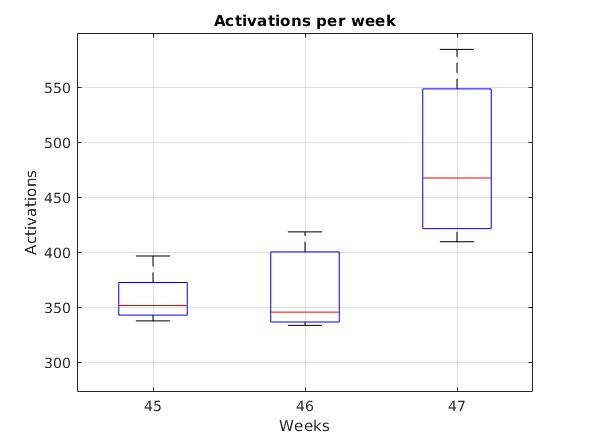


% Boxplot
group = [
    1 * ones(size(data_w1))
    2 * ones(size(data_w2))
    3 * ones(size(data_w3))
];
boxplot([data_w1; data_w2; data_w3], group, "Labels", {45, 46, 47})
grid on
title("Activations per week")
xlabel("Weeks")
ylabel("Activations")


% Hypothesis tests
disp("Hypothesis 1: People will use the hand-sanitising foam dispenser differently depending on the visual stimuli that accompanies it.")

Hypothesis 1: People will use the hand-sanitising foam dispenser differently depending on the visual stimuli that accompanies it.


disp("W1 not equal to W2")

W1 not equal to W2


[h, p, CI, stats] = ttest2(data_w1, data_w2, "Vartype", "unequal")

h = 0

p = 0.8257

CI =  -105.3853
   91.5186


stats = struct with fields:
    tstat: -0.2431
       df: 2.6300
       sd: [2×1 double]

disp("W1 not equal to W3")

W1 not equal to W3


[h, p] = ttest2(data_w1, data_w3, "Vartype", "unequal")

h = 1

p = 0.0166


disp("Hypothesis 2: People will use the hand-sanitising foam dispenser more frequently when it is accompanied by interesting visual stimuli.")

Hypothesis 2: People will use the hand-sanitising foam dispenser more frequently when it is accompanied by interesting visual stimuli.


disp("W1 smaller than W3")

W1 smaller than W3


[h, p] = ttest2(data_w1, data_w3, "Vartype", "unequal", "Tail", "left")

h = 1

p = 0.0083

disp("W2 smaller than W3")

W2 smaller than W3


[h, p] = ttest2(data_w2, data_w3, "Vartype", "unequal", "Tail", "left")

h = 1

p = 0.0160